% Create figure and tile layout
figure('Position',  [500, 500, 800, 1100])
tiledlayout(6,2, 'TileSpacing', 'compact', 'Padding', 'compact')

% ================= Blue LED ================= %
nexttile
d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\BLED.txt");
lambda = d(:,1);
Ia = d(:,2);
Ia = normalize_intensity(Ia);
plot(lambda, Ia, "Color", [0 0 1], 'LineWidth', 1.02)
title('Blue LED Spectrum', "Interpreter", "latex");
xlabel('$\lambda$ (nm)', "Interpreter", "latex");
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'TickLength', [0.02, 0.04], ...
    'LineWidth', 0.5);
xlim([200 700])
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

% ================= Red LED ================= %
nexttile
d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\RLED.txt");
Ib = d(:,2);
Ib = normalize_intensity(Ib);
plot(lambda, Ib, "Color", [1 0 0], 'LineWidth', 1.02)
title('Red LED Spectrum', "Interpreter", "latex");
xlabel('$\lambda$ (nm)', "Interpreter", "latex");
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'TickLength', [0.02, 0.04], ...
    'LineWidth', 0.5);
xlim([400 800])
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

% ================= Green LED ================= %
nexttile
d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\GLED.txt");
Ic = d(:,2);
Ic = normalize_intensity(Ic);
plot(lambda, Ic, "Color", [0 1 0], 'LineWidth', 1.02)
title('Green LED Spectrum', "Interpreter", "latex");
xlabel('$\lambda$ (nm)', "Interpreter", "latex");
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'TickLength', [0.02, 0.04], ...
    'LineWidth', 0.5);
xlim([300 800])
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

% ================= Yellow LED ================= %
nexttile
d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\YLED.txt");
Id = d(:,2);
Id = normalize_intensity(Id);
plot(lambda, Id, "Color", "#FFBF00", 'LineWidth', 1.02)
title('Yellow LED Spectrum', "Interpreter", "latex");
xlabel('$\lambda$ (nm)', "Interpreter", "latex");
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'TickLength', [0.02, 0.04], ...
    'LineWidth', 0.5);
xlim([300 900])
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid


% ================= White LED ================= %
nexttile
d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\WLED.txt");
Ie = d(:,2);
Ie = normalize_intensity(Ie);
plot(lambda, Ie, "Color", [0.5 0.5 0.5], 'LineWidth', 1.02)  % Changed to gray for white LED
title('White LED Spectrum', "Interpreter", "latex");
xlabel('$\lambda$ (nm)', "Interpreter", "latex");
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'TickLength', [0.02, 0.04], ...
    'LineWidth', 0.5);
xlim([200 900])
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

% ================= HeNE Laser ================= %
nexttile
d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\RLASER.txt");
If = d(:,2);
If = normalize_intensity(If);
plot(lambda, If, "Color", [1 0 0], 'LineWidth', 1.02)
title('HeNe Laser Spectra', "Interpreter", "latex");
xlabel('$\lambda$ (nm)', "Interpreter", "latex");
ylabel('Intensity', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'TickLength', [0.02, 0.04], ...
    'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid
xlim([500 770])

f = gcf();

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [500 500 800 1100]
       Units: 'pixels'

  Show all properties


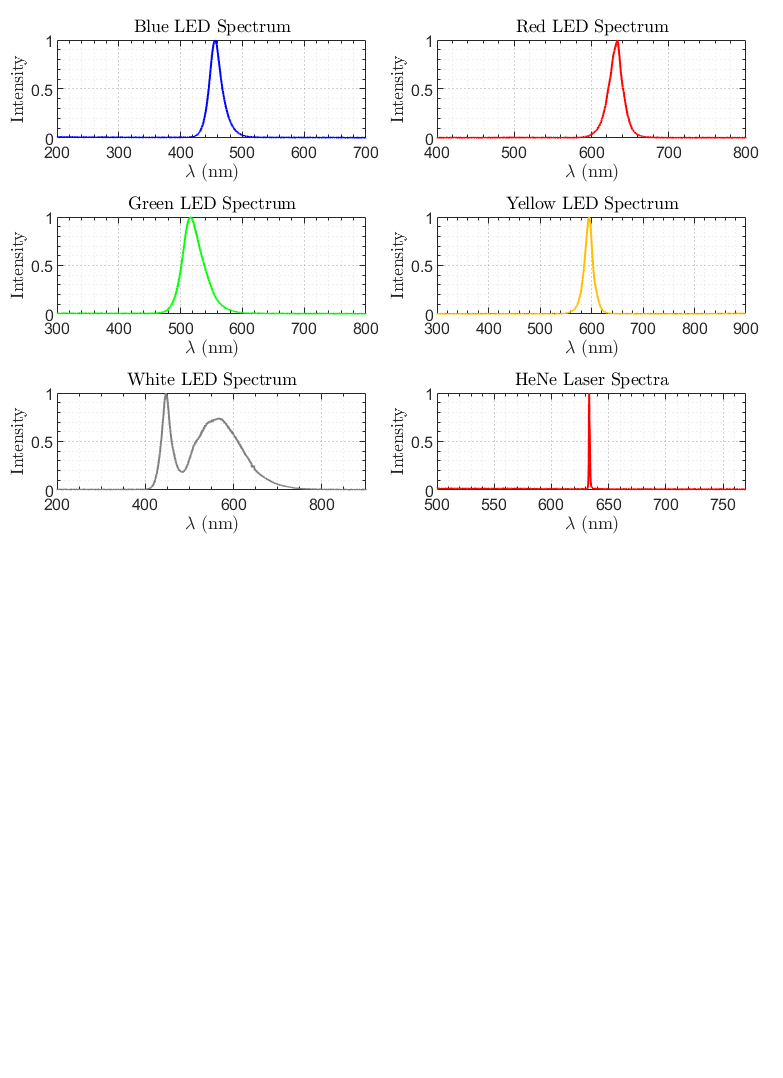

exportgraphics(f, 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\SpectrumStack.pdf')

function norm_I = normalize_intensity(I)
    norm_I = (I - min(I))./(max(I)-min(I));
end